Name: Yusu (Cosmo) Zhao

Student Number: 20761282

PartA:

 1. 

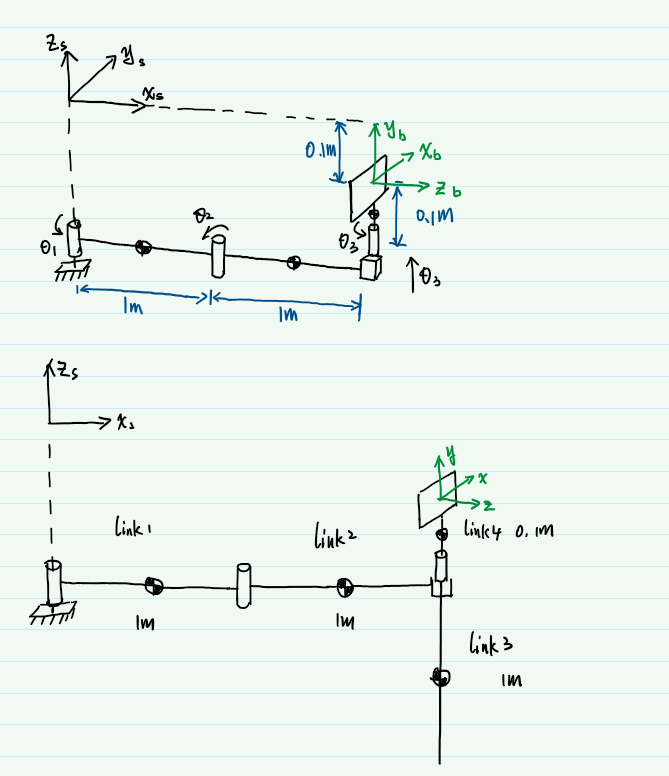

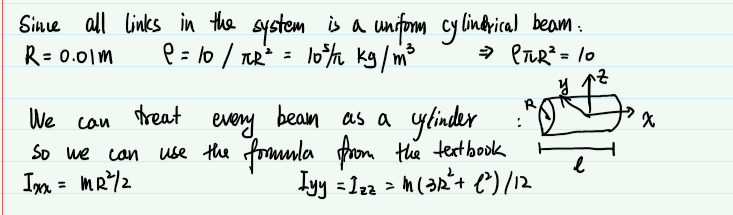

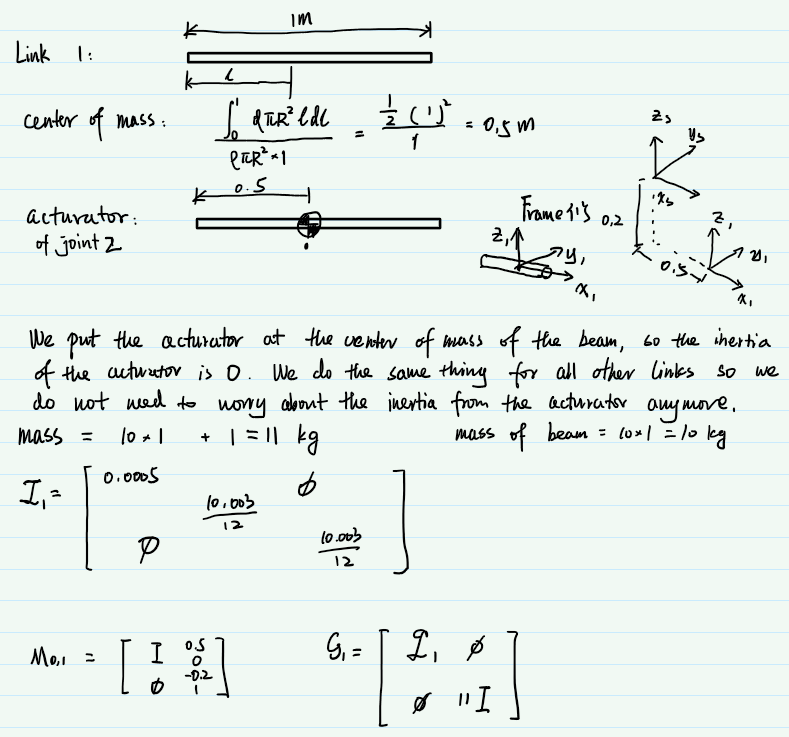

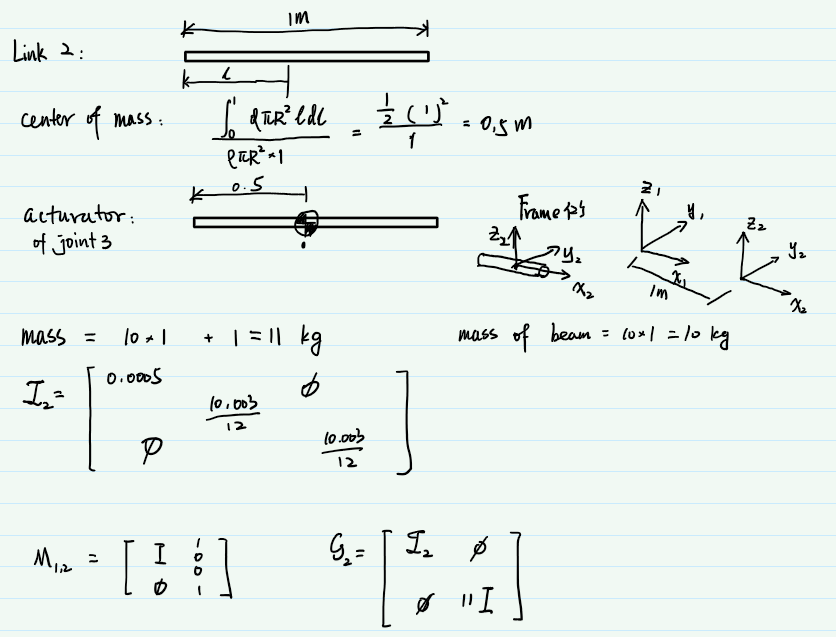

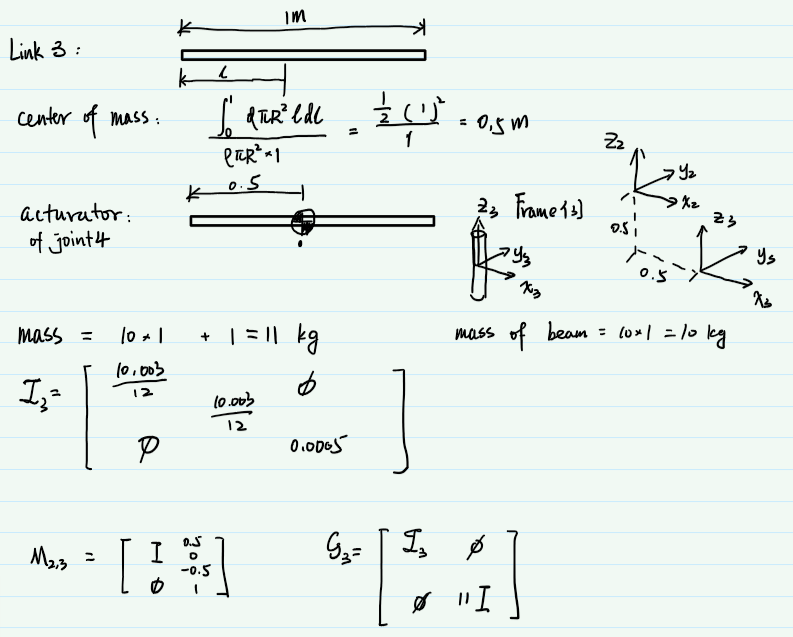

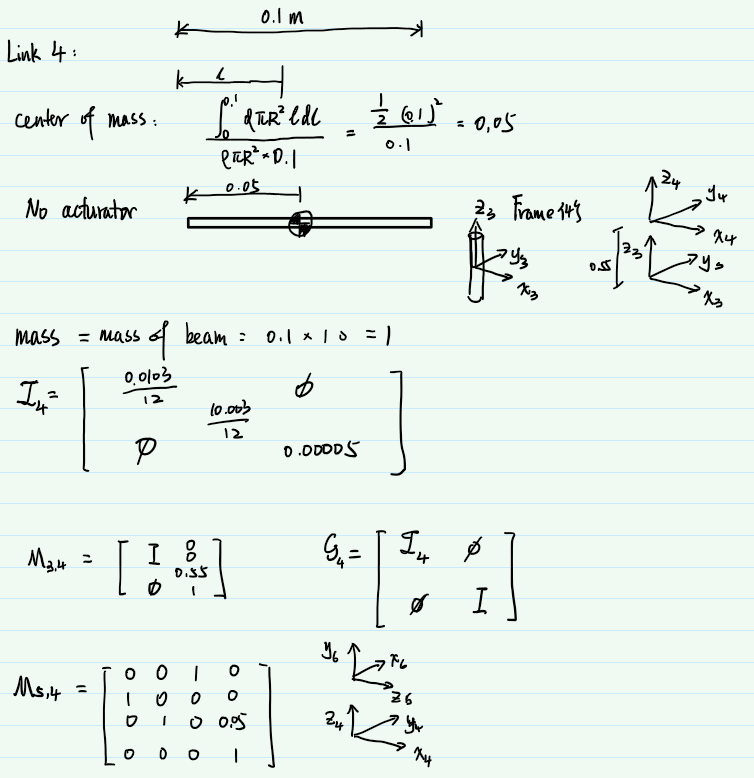

3. 

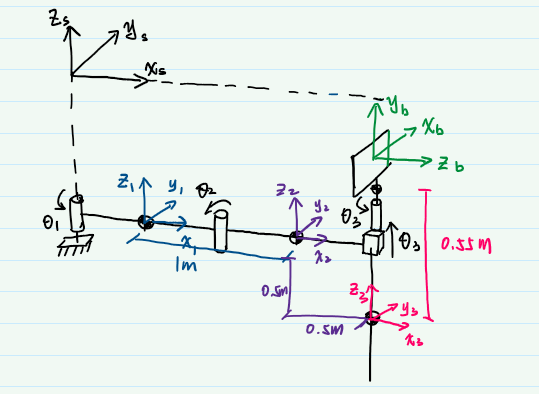

PartB:

- The code is straightfoward. I copy-pasted code from previous sessions with modifications to adapt my changes in the robot design. Those code includes utility functions. Then, I input the mass matrices and frame transformation matrices as stated above. This piece of code can be used in the force control to calculate the acceleration and the force. They can also be used as a verification. 

% Add the MATLAB library provided by http://modernrobotics.org
unzip('mr.zip');
ikFun = @inverse_kinematics;
genTraj = @generate_trajectory;

% Constants:
% T_sh - home pose of the paddle (relative to the fixed frame)
% g - acceleration due to gravity (relative to the fixed frame)
R_sh = [0 1 0; 0 0 1; 1 0 0]';
p_sh = [0.25 0 0.25]';
T_sh = RpToTrans(R_sh, p_sh);
g = [0; 0; -9.8];

% Robot Design (copied from Section 3: Design or your revised design)
% Define joint_types, joint_limits, B_list, S_list, and M
joint_types = ['R','R','P','R']; % the types of joints you have using a row vector of 'R' and 'P' elements
joint_limits = [[-pi;pi],[0;pi],[0;1],[-pi;pi]]; % must have the dimensions [2, n_joints]
S_list = [[0;0;1;0;0;0],[0;0;1;0;-1;0],[0;0;0;0;0;1],[0;0;1;0;-2;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
B_list = [[0;1;0;2;0;0],[0;1;0;1;0;0],[0;0;0;0;1;0],[0;1;0;0;0;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
M = [[0,0,1,2];[1,0,0,0];[0,1,0,-0.1];[0,0,0,1]]; % must be in SE(3)

speed_limits(joint_types == 'P') = 0.5;
speed_limits(joint_types == 'R') = 2;
n_joints = length(joint_types);

% Robot Dynamic Parameters
% Define M_list and G_list

M01 = vertcat(horzcat(eye(3), [0.5;0;-0.2]), [0 0 0 1]); % must be a 4x4 homogeneous transformation matrix (i.e., in SE(3))
M12 = vertcat(horzcat(eye(3), [1;0;0]), [0 0 0 1]); % must be a 4x4 homogeneous transformation matrix (i.e., in SE(3))
M23 = vertcat(horzcat(eye(3), [0.5;0;-0.5]), [0 0 0 1]); % must be a 4x4 homogeneous transformation matrix (i.e., in SE(3))
M34 = vertcat(horzcat(eye(3), [0;0;0.55]), [0 0 0 1]);
M45 = vertcat([[0;1;0], [0;0;1], [1;0;0], [0;0;0.05]], [0 0 0 1]);

M_list = cat(3, M01, M12, M23, M34, M45); % concatenates the matrices into a list of n+1 matrices

G1 = blkdiag(diag([0.0005, 10.003/12, 10.003/12]) , 11 * eye(3)); % must be a 6x6 matrix with a 3x3 rotational inertia in the top left corner and mass*eye(3) in the bottom right corner
G2 = blkdiag(diag([0.0005, 10.003/12, 10.003/12]) , 11 * eye(3));
G3 = blkdiag(diag([10.003/12, 10.003/12, 0.0005]) , 11 * eye(3));
G4 = blkdiag(diag([0.0103/12, 0.0103/12, 0.00005]) , 1 * eye(3));

G_list = cat(3, G1, G2, G3, G4); % concatenates the matrices into a list of n matrices
% Inverse Kinematics function (copied from the IK problem in Section 4: Validation)
% NOTE: This function has been modified so you can pass it p_sb *or* T_sc
% Inputs
% p_sb - The position of the ball (in the fixed frame)
% OR
% T_sc - The desired contact pose of the paddle (in the fix`ed frame)
% Outputs
% T_sc - The desired contact pose of the paddle (in the fixed frame)
% solution_list - A matrix of all valid IK solutions where each row is a list of joint positions. Empty matrix if no valid solution found.

function [T_sc, solution_list] = inverse_kinematics(var)
if size(var)==[4 4] & TestIfSE3(var)
    % The input variable is in SE(3), so set T_sc to the input
    T_sc = var;
else
    % The input variable is not in SE(3), so set p_sb to the input
    p_sb = reshape(var,[3,1]);

    % Generate a desired contact pose T_sc given the ball position p_sb
    % Note: Copy this section from the IK problem in Section 4: Validation
    contact_angle = 0;
    [T_sc] = make_contact(p_sb, contact_angle);
end

% Find all valid solutions of the IK problem for your robot to place the paddle in pose T_sc
% Note: Copy this section from the IK problem in Section 4: Validation
% Note: If T_sc is provided, it may be the home pose outside the cuboid
if size(var)==[4 4] & TestIfSE3(var)
    contact_angle = 0;
    p_sb = var(1:3,4);
elseif any(p_sb > [1.1;0.8;0.7] | p_sb < [0.3;-0.8;-0.1])
    solution_list = [];
    return;
end

    x = T_sc(1,4);
    y = T_sc(2,4);
    z = T_sc(3,4);
    gamma = atan2(y, x);
    alpha = acos((x.^2 + y.^2) / (2 * sqrt(x.^2 + y.^2)));
    theta1 = gamma - alpha;
    beta = acos(1 - (x.^2 + y.^2) / 2);
    theta2 = pi - beta;
    theta3 = z + 0.1;
    theta4 = - (theta1 + theta2);
    
    solution_list = [[theta1 theta2 theta3 theta4]]; % Each row is a valid set of joint positions
end

% Inputs
% p_sb - The position of the ball at time tc (in the fixed frame)
% t_c - The time at which the ball will be at p_sb
% freq - The sampling frequency (in Hz) used to generate your trajectory
% Outputs
% joint_traj - A matrix defining a joint trajectory were each row is a set of joint positions. Empty matrix if no solution found.
function joint_traj = generate_trajectory(p_sb, t_c, freq)
    % Find all valid configurations which contact the ball at p_sb
    [~, goal_configs] = inverse_kinematics(p_sb)
    if isempty(goal_configs)
        joint_traj = [];
        return;
    end
    
    % Find all valid home configurations
    T_sh = RpToTrans([0 1 0; 0 0 1; 1 0 0]', [0.25 0 0.25]');
    [~, home_configs] = inverse_kinematics(T_sh);

% Find a valid trajectory for your robot to follow to end up with the paddle at rest in pose T_sc at or before t_c
    N = t_c * freq;
    home_configs
    joint_traj = JointTrajectory(home_configs',goal_configs',t_c,N + 1,5);
end
function [T_sc] = make_contact(p_sb, theta)
% Inputs:
% p_sb - fixed ball position (relative to the fixed frame)
% theta - desired paddle contact angle about a vertical axis

% Constants:
% T_sh - home pose of the paddle (relative to the fixed frame)
R_sh = [0 0 1; 1 0 0; 0 1 0];
p_sh = [0.25; 0; 0.25];
T_sh = RpToTrans(R_sh, p_sh);

% Generate:
% p_hb - the position of the ball (relative to the home pose),
% T_sc - the contact pose (relative to the fixed frame), and
% T_hc - the motion required to move from the home pose to the contact pose.

p_hb = TransInv(T_sh) * [p_sb; 1];
p_hb = p_hb(1:3);
omg = [0; 1; 0] * theta; % Rotation about the z-axis by theta
so3mat = VecToso3(omg);  % Calculate the skew
R_hc = MatrixExp3(so3mat); % Calculate the exponential
offset = (R_hc * [0;0;1]) * 0.01;
p_hc = p_hb - offset; % 0.01m away from the ball
T_sc = T_sh * RpToTrans(R_hc, p_hc);
end


Torque trajectories

For all plots below, joint 3 have a very large torque comparing to all other joints. This makes sense because that the structure of the robot indicating that the torque produced by its mass are mostly in the z-direction. All rotary joints here (joint one, two and four) are also along z-axis, so they do not need to contribute. However, that means joint 3 will need to handle almost all the masses in the robots when it moves, so it needs a large torque. 

Moving to center:

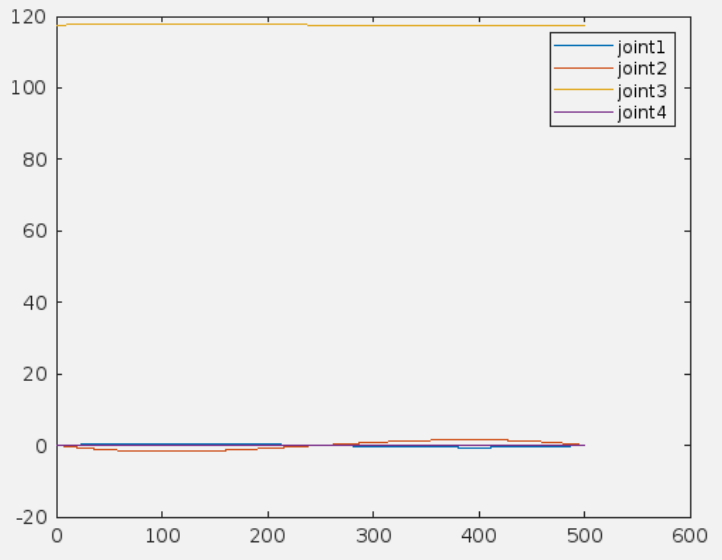

Moving to corner (0.3, 0.8, -0.1):

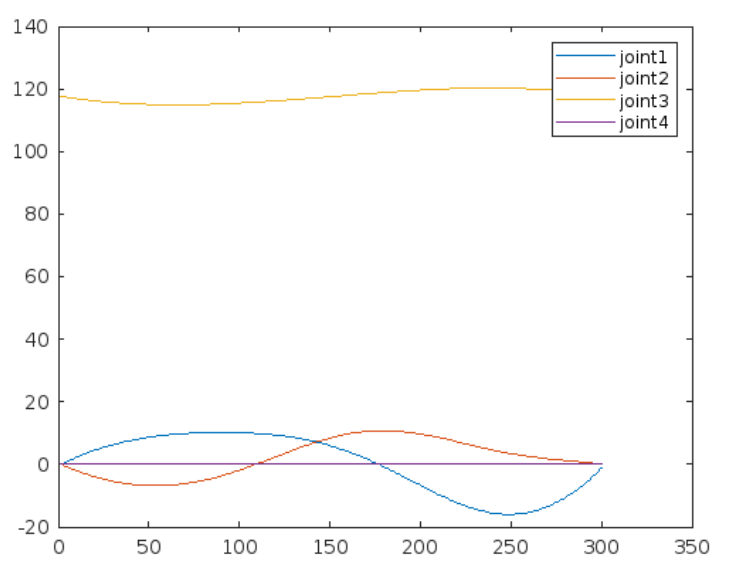

Moving to corner (0.3, -0.8, -0.1):

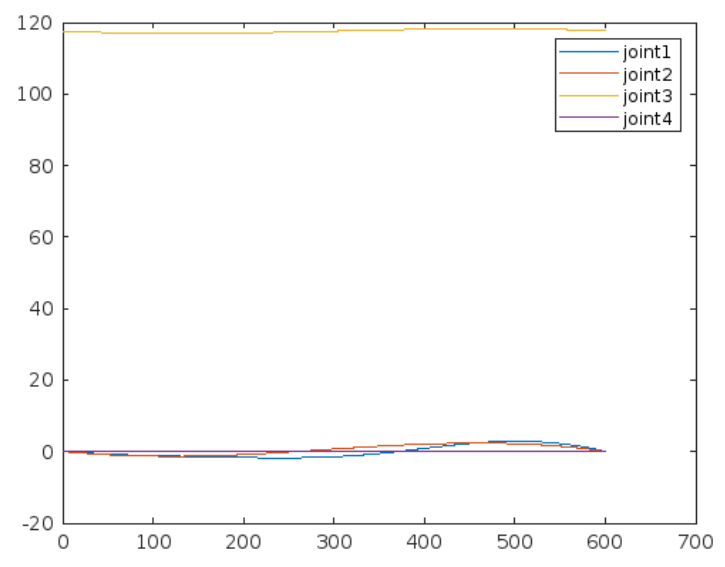

Moving to corner (0.3, 0.8, 0.7):

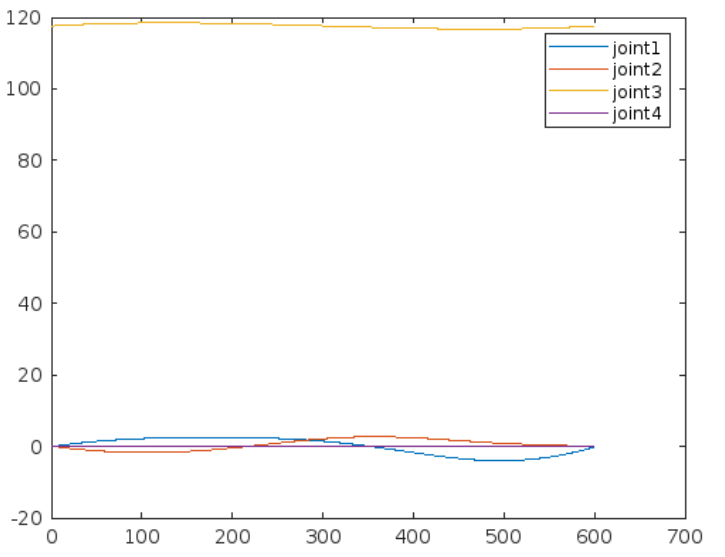

Moving to corner (0.3, -0.8, 0.7):

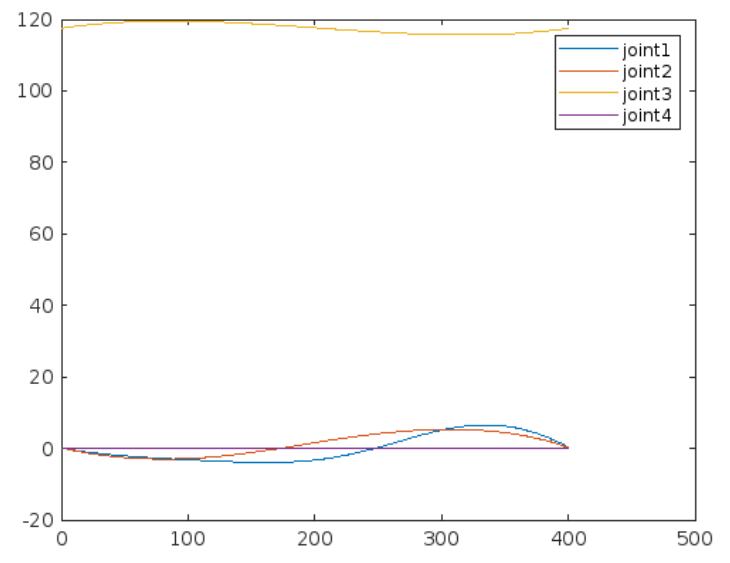

Moving to corner (1.1, 0.8, -0.1):

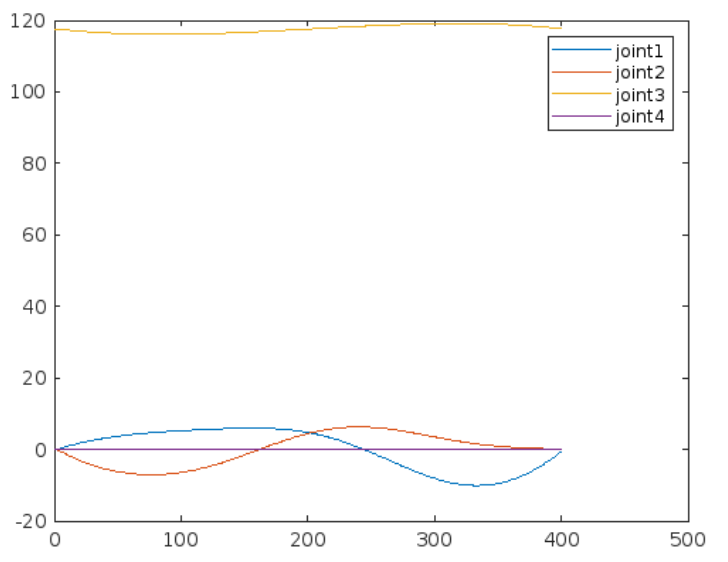

Moving to corner (1.1, -0.8, -0.1):

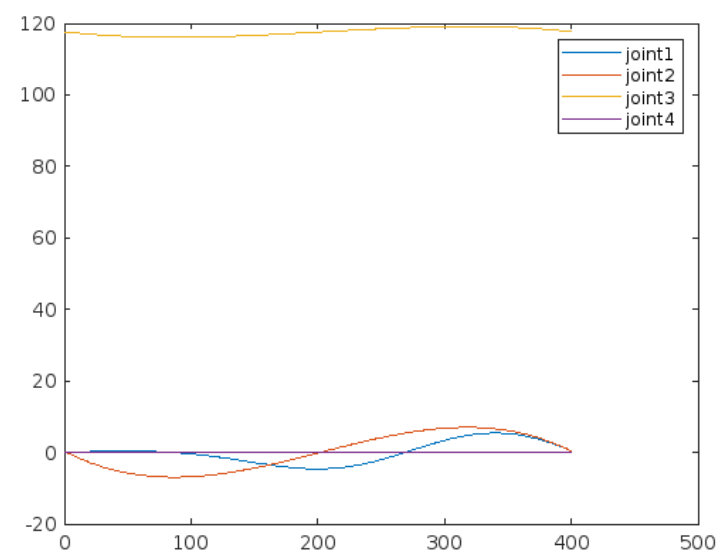

Moving to corner (1.1, 0.8, 0.7):

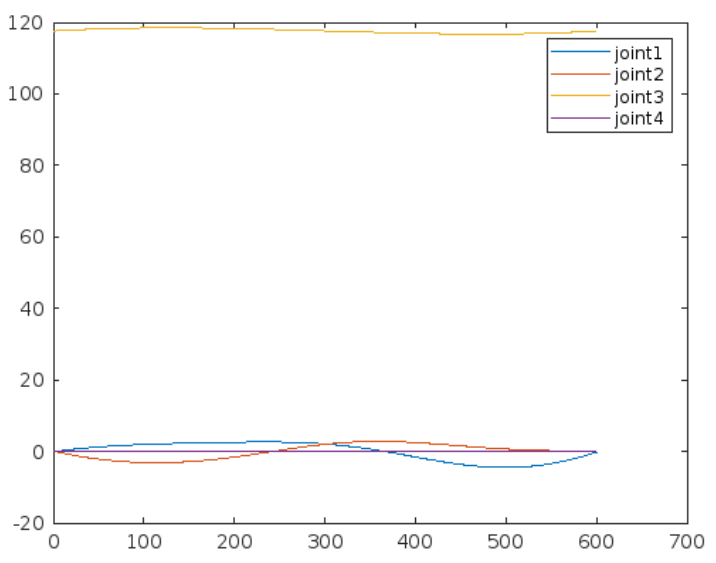

Moving to corner (1.1, -0.8, 0.7):